# Dynamic Modeling of a Two-wheeled Inverted Pendulum Balancing Mobile Robot 

https:%core.ac.uk/download/pdf/287648002.pdf


clear
      g = 9.8067;             %m/s^2 - Acceleration due to gravity.

%Model parameters based on V2 Prototype.
%--- Parameters of Geared Motor  ---
%From datasheet of 100:1 HP micrometal gear motor
Tstall = 0.021602;       %N-m - stall torque (2.2 kg/m).
RPMnoload = 320;        %No-load RPM at Vin=6V.
wnl = (RPMnoload*2*pi)/60;     %No load gearbox output shaft rotation velocity in rad/sec.
Inl = 0.06;             %No load current into motor, from measurement.
Vin = 6;                %Volt. Input voltage to armature during test.
Istall = 1.6;           %Amp, stall armature current.
Ng = 100;                %Gear ratio.
Dg = 0.00001;           %kgm/rad/sec - Viscous loss of gear.
La = 0;                 %Assume armature inductance is 0.

Ra = Vin/Istall;            %Armature resistance.
Kt = (Tstall/(Vin*Ng))*Ra;   %Armature torque constant.
Kb = (Vin-Ra*Inl)/(wnl*Ng);           %Armature back EMF constant.

%--- Parameters of Motor Driver  ---
Kmd = 3.16;             %Voltage gain of motor driver.

%--- Parameters of Wheel ---
R = 0.035;              %m - Radius of wheel, 70mm 3D printed wheels.
mw = 0.0343;            %kg - Mass of wheel.
Jw = 0.5*mw*R*R;        %kgm2 - Moment inertia of wheel reference to the center (axle).
                        %This is approximate only, assuming uniform mass distribution.
%--- Parameters of Robot Body ---
mb = 0.2445;            %kg - Mass of body.
lb = 0.035;             %m - Distance of center of mass to wheel axle.
Jb = 0.1*mb*lb*lb;     %kgm2 - Moment inertia of Body reference to the center of mass.

## State Space Control

% 2D Model
syms s Va theta_m theta_b xpos
% Auxilialy Variables
Cm1 = Ng*Kt/Ra;
Cm2 = Cm1*Kb;
M = mb + 2*(mw+Jw/(R*R)) - ((mb*mb*lb*lb)/(mb*lb*lb + Jb));
J = (mb*lb*lb) + Jb - ((mb*mb*lb*lb)/(mb + 2*(mw+Jw/(R*R))));
C1 = (1/M)*((mb*mb*lb*lb*g)/(Jb + mb*lb*lb));
C2 = (2/M)*((1/R) + ((mb*lb)/(Jb + mb*lb*lb)));
C3 = (mb*lb*g)/J;
C4 = (2/(J*R))*(R + ((mb*lb)/(mb + 2*(mw + Jw/(R*R)))));


% State Space System     
X = [xpos; s*xpos; theta_b; s*theta_b]

$$X = \left[\begin{array}{c} \mathrm{xpos}\\ s\,\mathrm{xpos}\\ \theta_{b}\\ s\,\theta_{b} \end{array}\right]$$

A = [0          1       0   0; 
    0 (-C2*Cm2/(R*Ng)) -C1 C2*Cm2;
    0           0       0   1;
    0 (C4*Cm2)/(R*Ng)   C3 -C4*Cm2]

A =          0    1.0000         0         0
         0   -0.0015  -17.4204    0.0054
         0         0         0    1.0000
         0    0.0509  707.1963   -0.1782



B = [0; C2*Cm1*Kmd; 0; -C4*Cm1*Kmd]

B =          0
    9.9190
         0
 -326.6995


C = eye(4,4)

C =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D = eye(4,1)

D =      1
     0
     0
     0


rank(obsv(A,C))

ans = 4

rank(ctrb(A, B))

ans = 4

P = ss(A,B,C,D)


P =
 
  A = 
              x1         x2         x3         x4
   x1          0          1          0          0
   x2          0  -0.001546     -17.42   0.005409
   x3          0          0          0          1
   x4          0    0.05091      707.2    -0.1782
 
  B = 
           u1
   x1       0
   x2   9.919
   x3       0
   x4  -326.7
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   1
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


%% LQR COONTROLLER
Q = diag([2 2 0.5 0.1])

Q =     2.0000         0         0         0
         0    2.0000         0         0
         0         0    0.5000         0
         0         0         0    0.1000


R = 2;
K = lqr(P,Q,R)

K =    -1.0000   -1.5754   -5.1649   -0.3343



Pcl = ss(A-B*K,B,C,D)


Pcl =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2   9.919   15.62   33.81   3.321
   x3       0       0       0       1
   x4  -326.7  -514.6  -980.2  -109.4
 
  B = 
           u1
   x1       0
   x2   9.919
   x3       0
   x4  -326.7
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   1
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


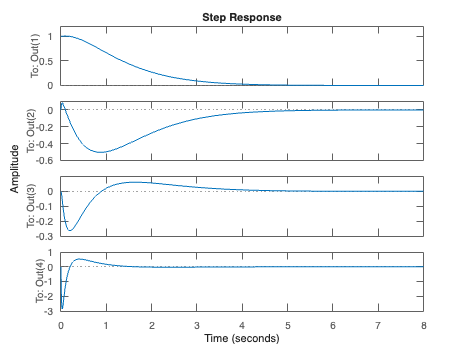

step(Pcl)